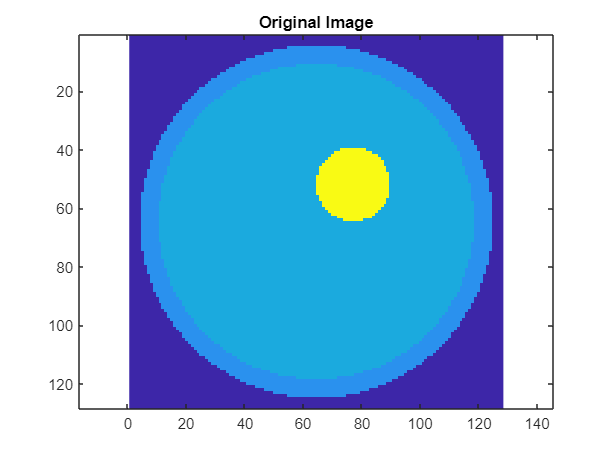

% Written by KhaiNguyen

imagesc(IMG50)
title('Original Image')
colormap(parula), axis('equal') 

**Question 3:**

% plot images of PSF on subplot
% compare filters

% How choice of projection angles & choice of filter affect image quality
% USE imagec(log10(abs(IMG)), [-10,0]
IMG = zeros(N,N);
IMG(N/4,N/4) = 1; % single non-zero point. Location doesn't matter

% ----- for loop -----
theta = [0:179]; % 180 projection angles ---- theta = # of projection angles
[p,r] = radon(IMG,theta);  % radon func add just number of pixels at each angle (diag = side*sqrt(2))



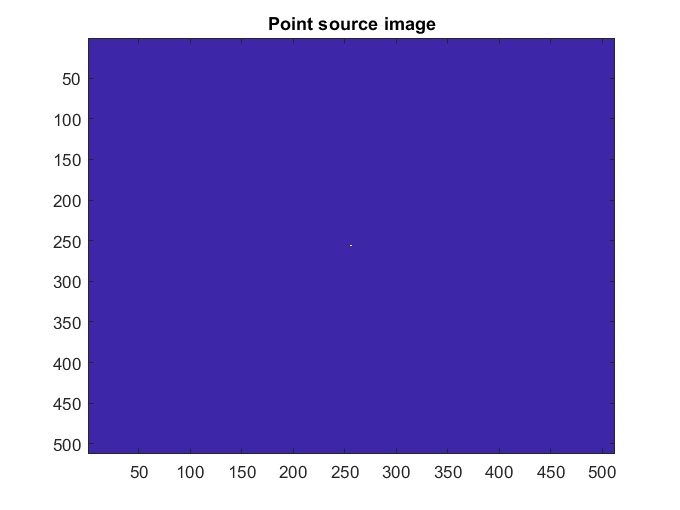

close all
N = 512;
IMGp = zeros(N,N);
IMGp((N)/2,(N)/2) = 1;
imagesc(IMGp)
title("Point source image")

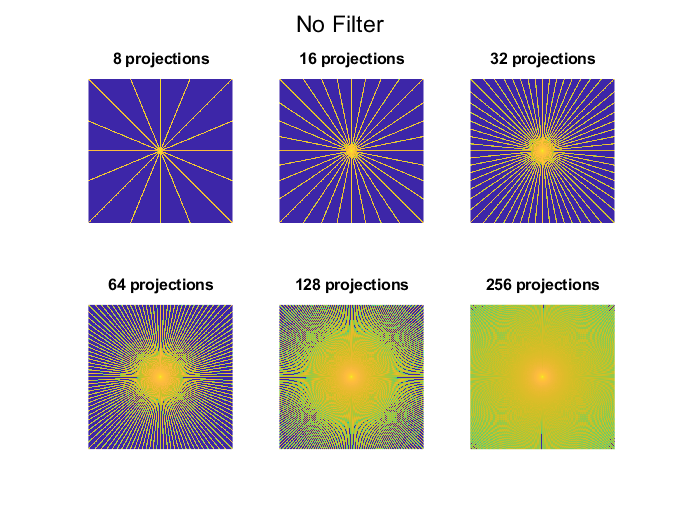

num_angles = [8, 16, 32, 64, 128, 256];
% ------------------ NO FILTER -------------------
% figure
% for k = 1:length(num_angles)
%     subplot(2,3,k)
%     for Np = 1:1:num_angles(k)
%         kp = [0:180/Np:179];
%         [p,r] = radon(IMGp,kp);
%         hb = iradon(p,kp,'linear','none'); % no filter
%         h = surf(hb);
%         set(h,'LineStyle','none','FaceColor','interp');
%         
%         title([int2str(Np),' projections'])
%         if Np <32
%             pause(0.5)
%         else
%             pause(.1)
%         end
%         
%     end
% end

% ---------- point source image --------------
figure
sgtitle("No Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','none'); % no filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

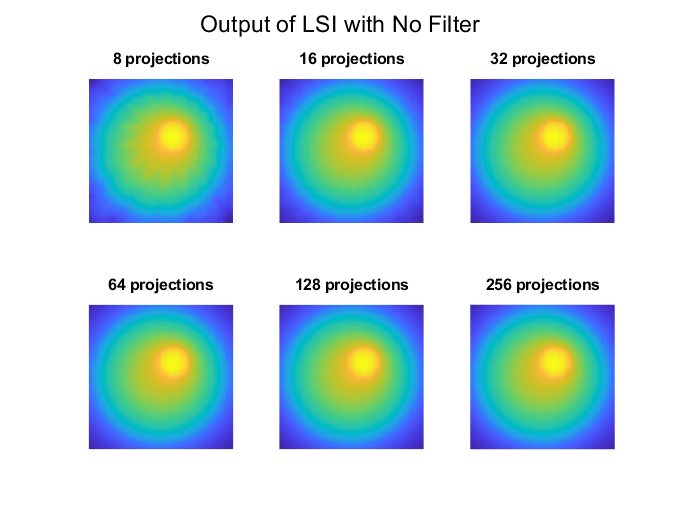


% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with No Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','none'); % no filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

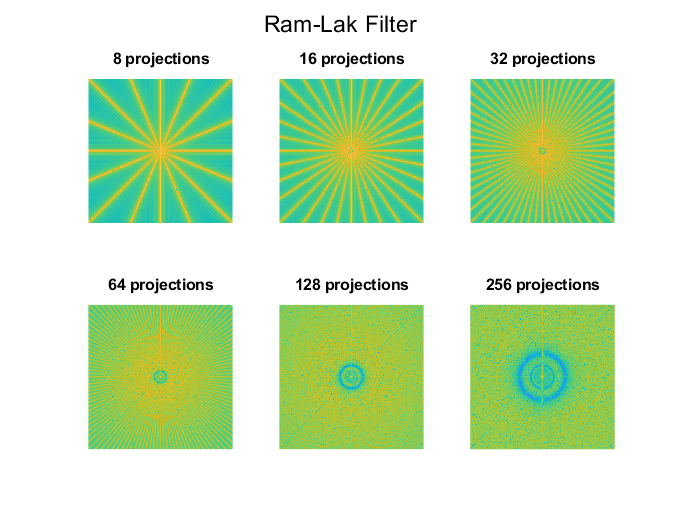

% ------------------ Ram-Lak FILTER -------------------
figure
sgtitle("Ram-Lak Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Ram-Lak'); % Ram-Lak filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

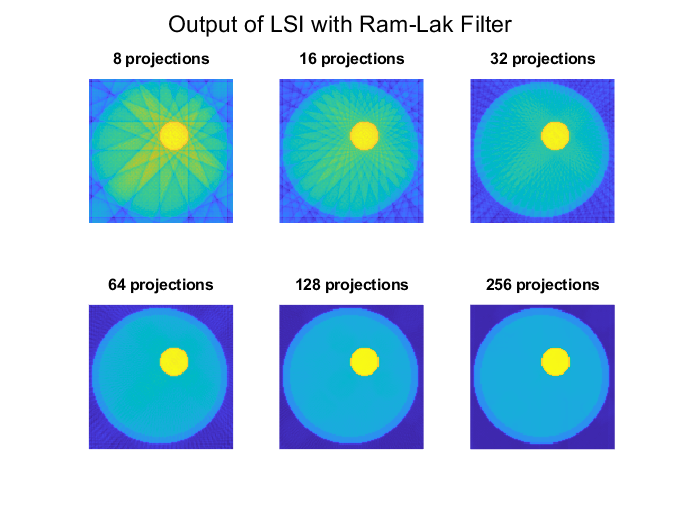


% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with Ram-Lak Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Ram-Lak'); % Ram-Lak filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

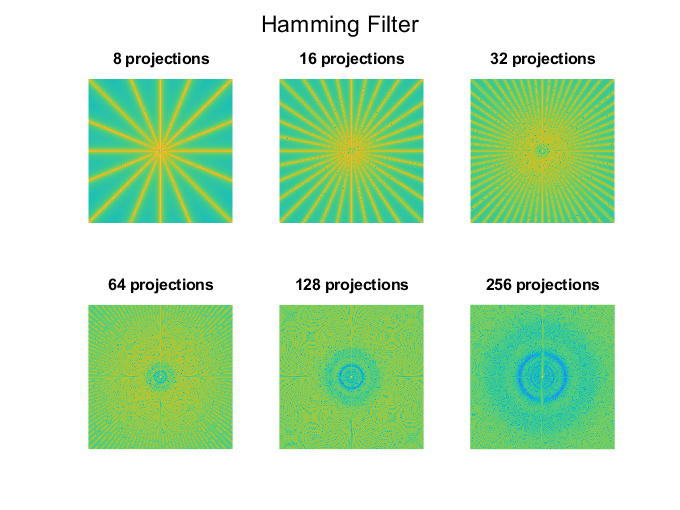

% ------------------ Hamming FILTER -------------------
figure
sgtitle("Hamming Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Hamming'); % Hamming filter
        imagesc(log10(abs(hb)),[-10,0]); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

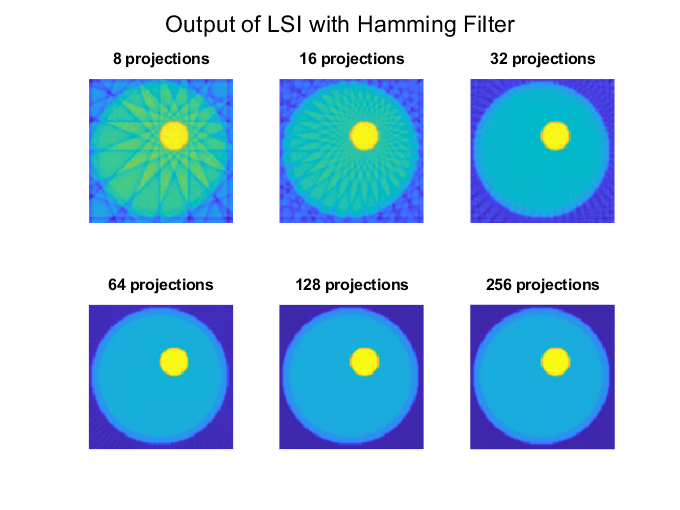

% ----------------- apply on original image ---------------
figure
sgtitle("Output of LSI with Hamming Filter")
for k = 1:length(num_angles)
    subplot(2,3,k)
    for Np = 1:1:num_angles(k)
        kp = [0:180/Np:179];
        [p,r] = radon(IMGp,kp);
        hb = iradon(p,kp,'linear','Hamming'); % Hamming filter
        IMG_LSI = conv2(IMG50,hb,'same');
        imagesc(IMG_LSI); axis('off'), axis('equal')
        title([int2str(Np),' projections'])
        if Np <32
            pause(0.5)
        else
            pause(.1)
        end
        
    end
end

From the images produced from convoluting IMG50 with each PSF, we see:

- With more projection angles, clearer reconstructed IMG50 is achieved. Also note that if we go more than 64 projections, image quality does not change significantly.

- Using no filter causes significantly more image blurring compared to having Ram-Lak and Hamming filters.

**Question 2: **Explain the Central Slice theorem.

The Central Slice theorem states that:

With $M(k_\mathrm{x},k_\mathrm{y})$ being the 2D FT of $\mu(x,y)$, 

and $P(k,\theta)$ being the 1D FT of $p(r,\theta)$, 

$P(k,\theta)$ is a line through $M(k_\mathrm{x},k_\mathrm{y})$.

First load the image:

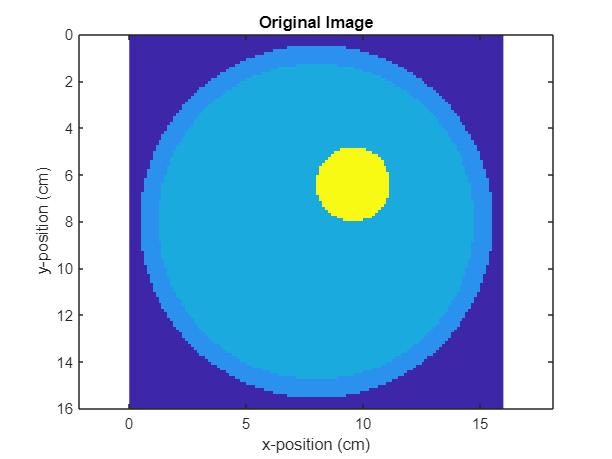

load example_image
dy = diff(y_index(1:2)); % sample period in the y direction
dx = diff(x_index(1:2)); % sample period in the x direction
[Ny,Nx] = size(IMG50);

figure
imagesc(y_index,x_index,IMG50), axis equal
xlabel('x-position (cm)')
ylabel('y-position (cm)')

title(['Original Image'])

With IMG50, we first compute $P(k,\theta)$ at $\theta = 0$:

% projection at theta = 0° - use trapazoidal approximation for integration
p_0 = trapz(y_index, IMG50, 1);

% Take the 1D fft of p_0.
P_0 = dy*fftshift(fft(p_0));

dk = 1./(Ny*dy);
k = (-1/2/dy:dk:(1/2/dy-dk))';

figure('Name','A3: Projection at theta = 0°')
semilogy(k,abs(P_0),'r-')
xlabel('k (cm^{-1})')
ylabel('P(k,\theta=0')
hold on

We then compute the corresponding **slice / line in** $M(k_\mathrm{x},k_\mathrm{y})$ **through the 2DFT of IMG50**. The slice we are looking at is in the central row of $M(k_\mathrm{x},k_\mathrm{y})$.

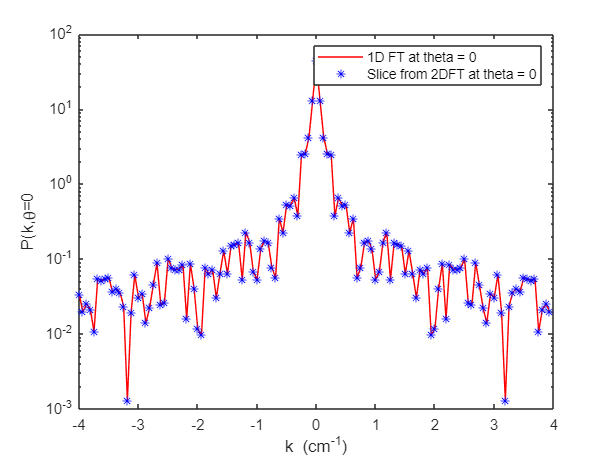

% 2D FT of IMG50
M = dx*dy*fftshift(fft2(IMG50));
% extract slice corresponding to projection @theta=0 
M_0 = M(Ny/2+1,:);
semilogy(k,abs(M_0),'b*')

legend('1D FT at theta = 0', 'Slice from 2DFT at theta = 0')

P_0 and M_0 aligns, Theorem proven.

Thus, with the Central Slice Theorem, if we have a sinogram $p(r,\theta)$, we can 1D FT to get $P(k,\theta)$. Then we can do more projections up to a certain number of angles to sufficiently sample $M(k_\mathrm{x},k_\mathrm{y})$ in a radial pattern. 

Next, we interpolate $M(k_\mathrm{x},k_\mathrm{y})$ into a Cartesian grid, and finally do a 2D Inverse Fourier Transform to get $\mu^{*}(x,y)$ as an estimate of $\mu(x,y)$.

However interpolation causes artifacts.